We look at the balance between the axial spring and the radial spring to lock the claw in position

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000

considering a constant spring constant we get the push of one **radial spring** from SODEMANN

theta = 15; %angle on ball lock
r_ball = 5e-3; %radius of the ball lock
% r_ball = 7.5e-3; %radius of the ball lock

k_radial = 12.16e3; % N/mm --> N/m %max compresion 13.80, total length 27.00; max force 169,66
% varenummer 12410
% alternatvi C06000981750M	
% syms k_radial
% k_radial = 24.22e3

x_radial = r_ball*sind(theta); %3; % mm compressed spring to hold
x_radial_mm = x_radial*1e3

x_radial_mm = 1.2941

F_spring_radial = k_radial*x_radial

F_spring_radial = 15.7362

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

g = 9.82;
m_claw = 1; %kg <--------- differ between claws
f_s = 0.30;
F_claw_fric = g * m_claw * f_s

F_claw_fric = 2.9460

- Due to the process of sliding over the ball also ads the friction of the ball pushing up. 

The normal force comes from the spring pushing up and it veries with movement. But since the normal force is stronger then the friction force we will alway have more force to hold with less angle on theta.

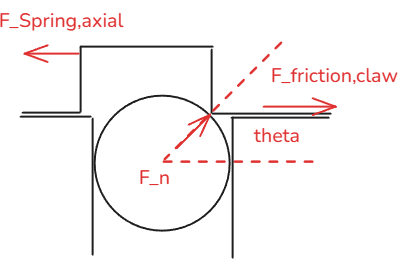

syms F_n_x

F_n_y = F_spring_radial + F_n_x * f_s;
F_n = F_n_y / sind(theta);

F_ball_fric_x = F_n_y * f_s; % sind(theta) * F__n * f_s

F_n_x_eq = F_n_x == F_spring_axial - F_ball_fric_x - F_claw_fric;

F_n_x_sol = solve(F_n_x_eq, F_n_x);

F_n_x_sol = double(F_n_x_sol)

F_n_x_sol = 30.2139

plot

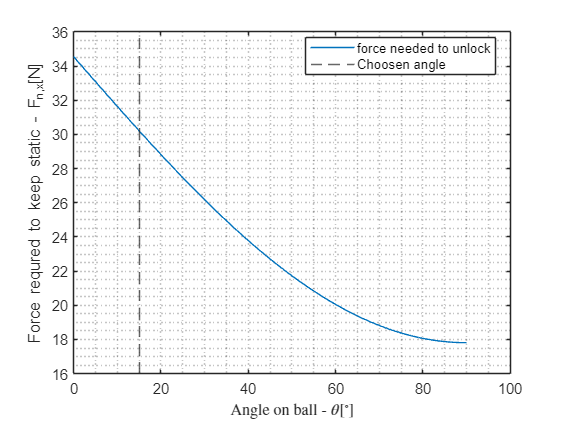

syms F_n_x
thetas = 0:1:90; %angle on ball lock
for i = 1:length(thetas)
    x_radial = r_ball*sind(thetas(i)); %3; % mm compressed spring to hold
    F_spring_radial = k_radial*x_radial;
    F_n_y = F_spring_radial + F_n_x * f_s;
    F_n = F_n_y / sind(thetas(i));
    
    F_ball_fric_x = F_n_y * f_s; % sind(theta) * F__n * f_s
    
    F_n_x_eq = F_n_x == F_spring_axial - F_ball_fric_x - F_claw_fric;
    
    F_n_x_sol = solve(F_n_x_eq, F_n_x);
    
    F_n_x_sols(i) = double(F_n_x_sol);
end

plot(thetas, F_n_x_sols, DisplayName="force needed to unlock")
hold on

xline(theta,'--', DisplayName="Choosen angle")
xlabel("Angle on ball - $\theta [^{\circ} ]$", Interpreter="latex")
ylabel("Force requred to keep static - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off

We sum the forces in the x-direction

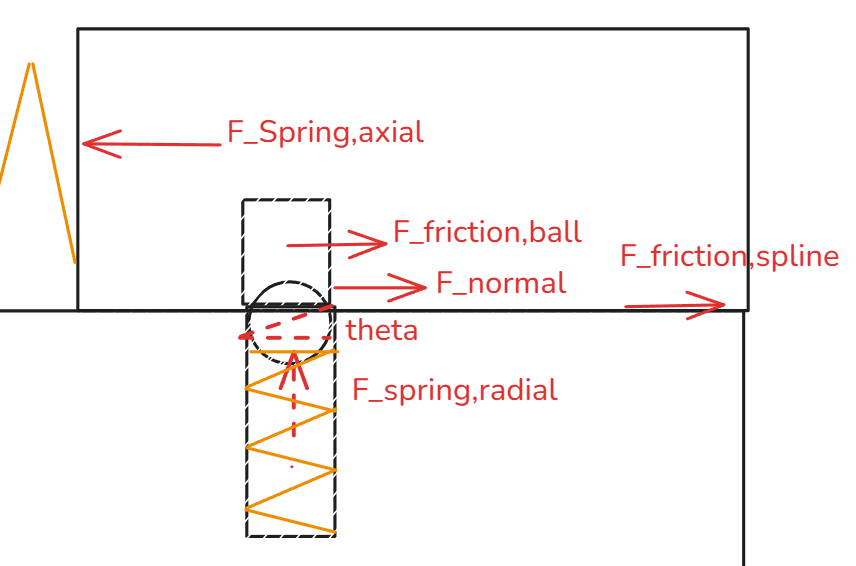

We sum the forces in the y-direction

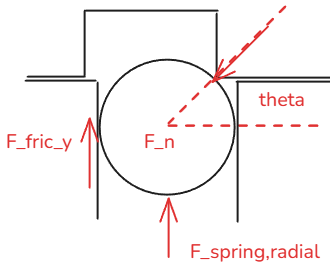

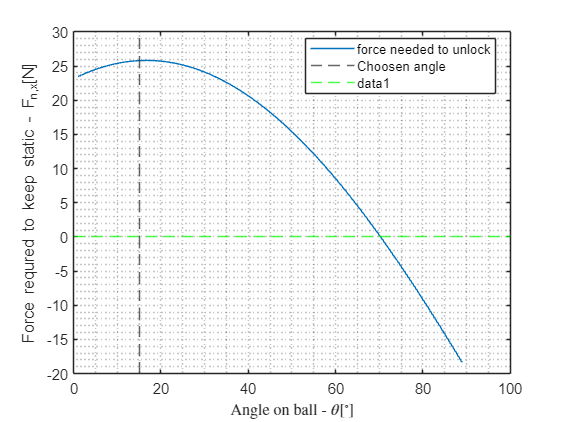

syms F_outer %F_spring_radial

thetas = 1:1:89; %angle on ball lock
for i = 1:length(thetas)
    x_radial = r_ball*sind(thetas(i)); %3; % mm compressed spring to hold
    F_spring_radial = k_radial*x_radial;
    
    
    F_n_y = F_spring_radial;
    F_n = F_n_y / sind(thetas(i));
    F_n_x_static = F_n * cosd(thetas(i));

    F_ball_fric_x = F_n_y * f_s; % sind(theta) * F__n * f_s
    
    F_x_eq_static = 0 == F_spring_axial - F_ball_fric_x - F_claw_fric - F_n * cosd(thetas(i)) + F_outer; %  F_claw_fric
    
    F_outer_sol = solve(F_x_eq_static, F_outer);
    
    F_outer_sols(i) = double(F_outer_sol);
end

plot(thetas, F_outer_sols, DisplayName="force needed to unlock")
hold on

xline(theta,'--', DisplayName="Choosen angle")
yline(0,'g--')
xlabel("Angle on ball - $\theta [^{\circ} ]$", Interpreter="latex")
ylabel("Force requred to keep static - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off